optrank_l = 1

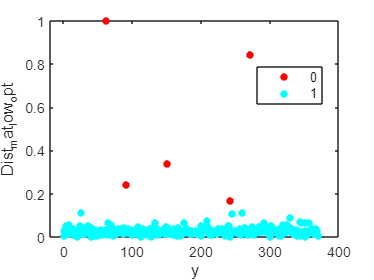

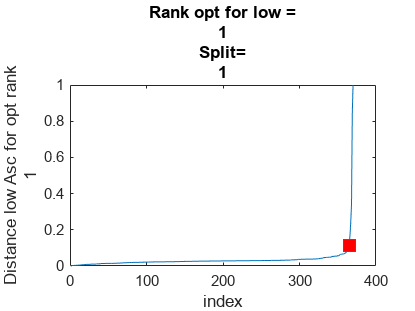

optrank_h = 8

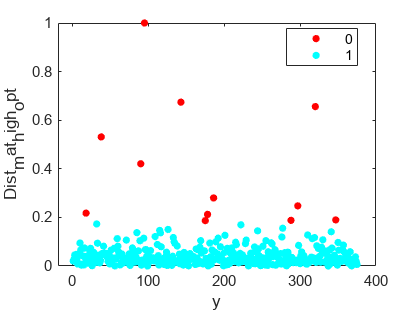

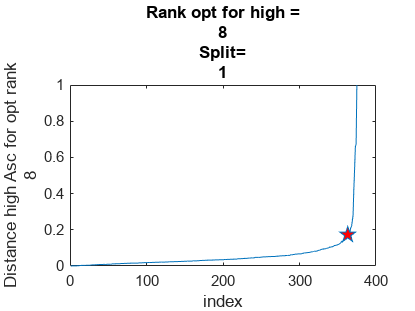

optrank_l = 1

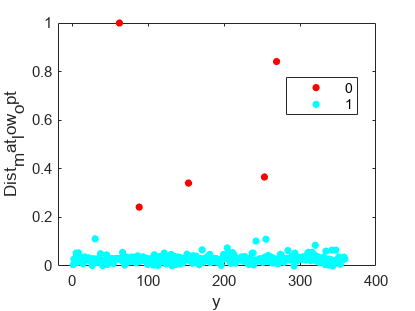

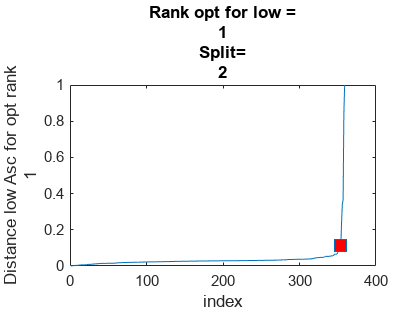

optrank_h = 1

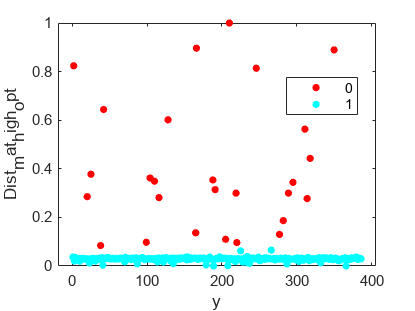

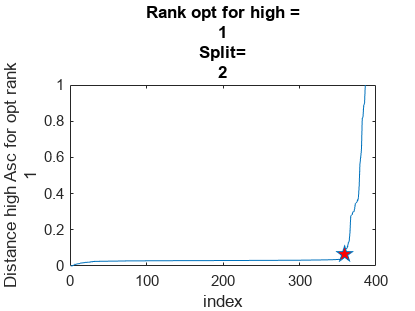

optrank_l = 1

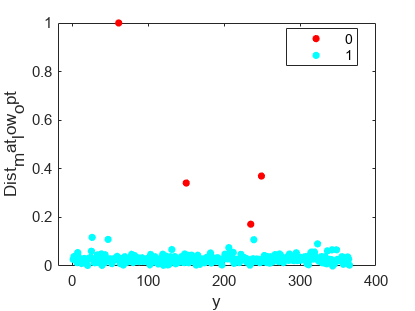

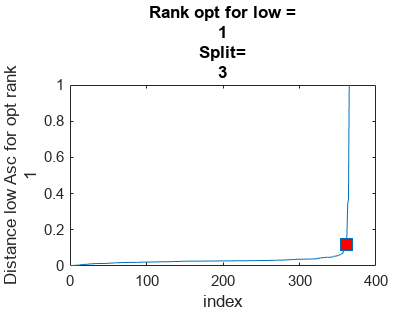

optrank_h = 1

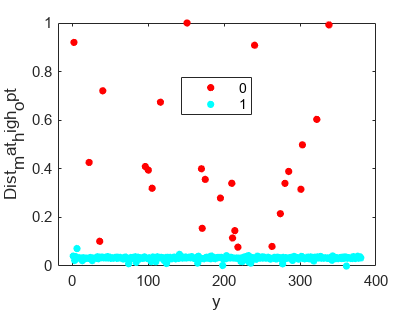

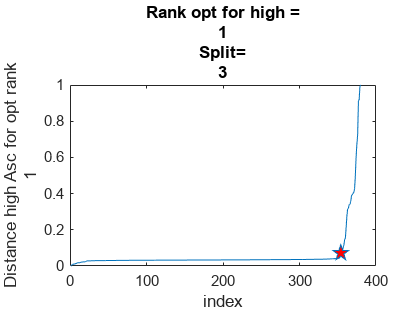

optrank_l = 1

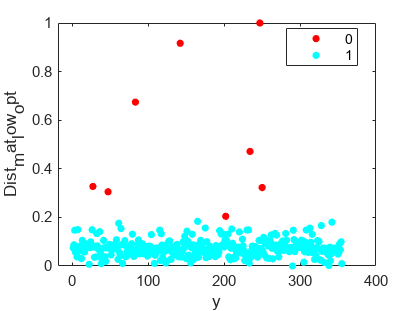

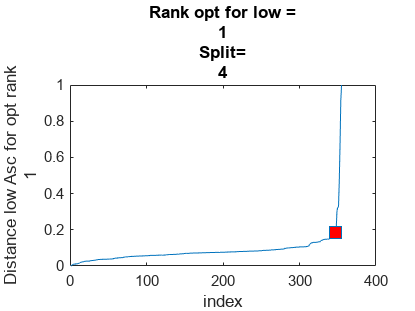

optrank_h = 1

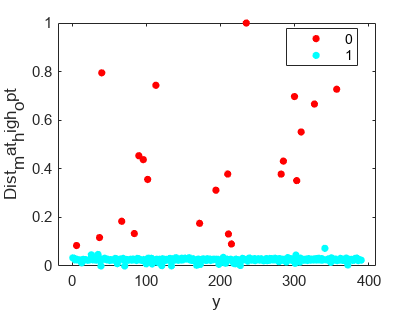

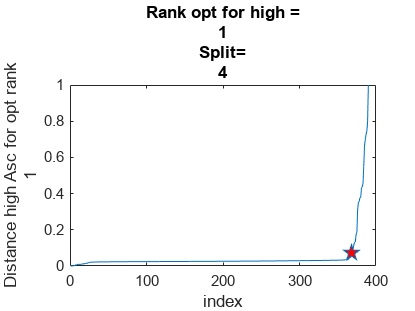

optrank_l = 1

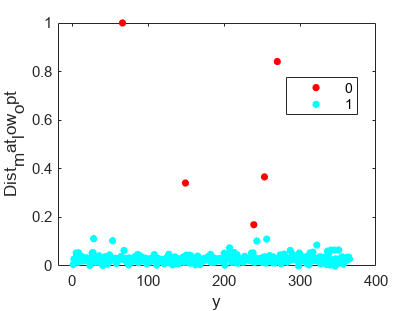

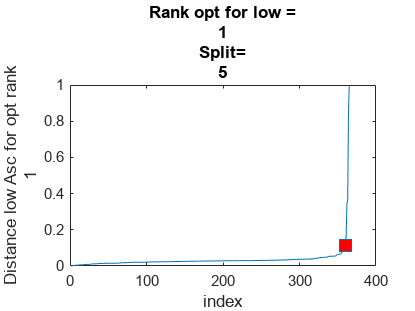

optrank_h = 1

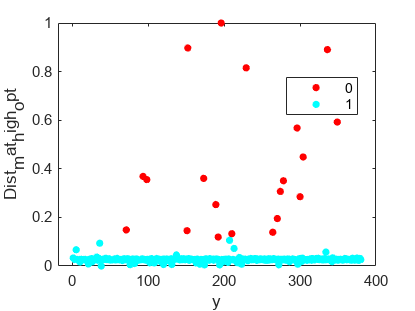

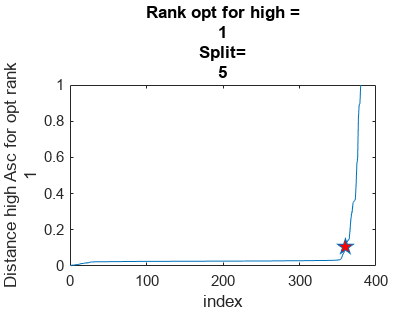

optrank_l = 1

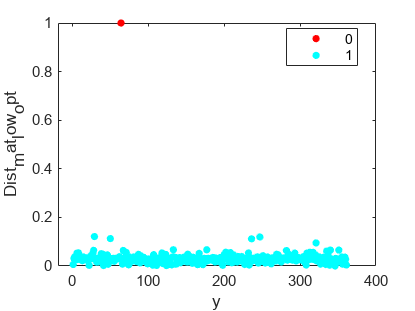

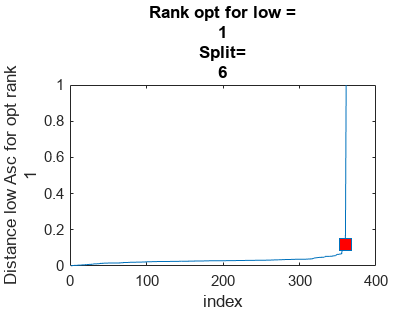

optrank_h = 1

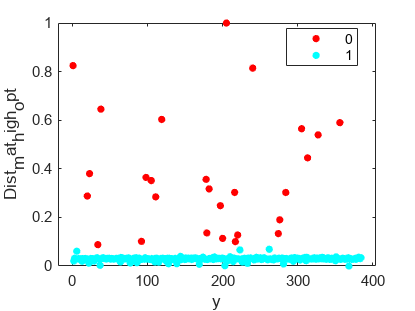

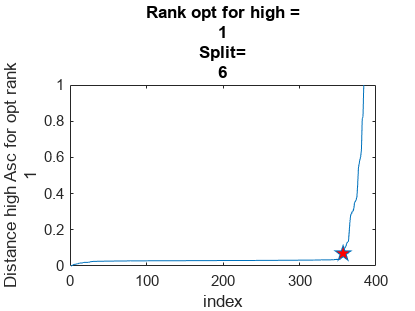

optrank_l = 1

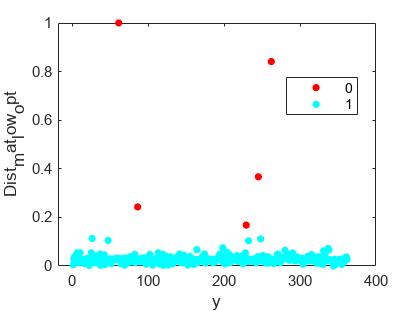

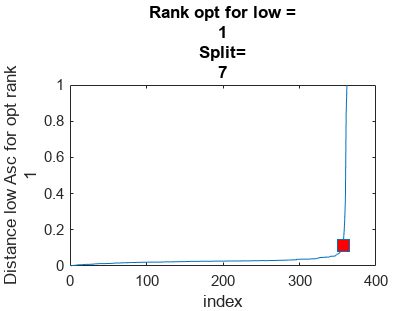

optrank_h = 1

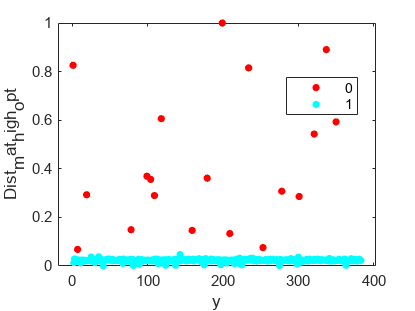

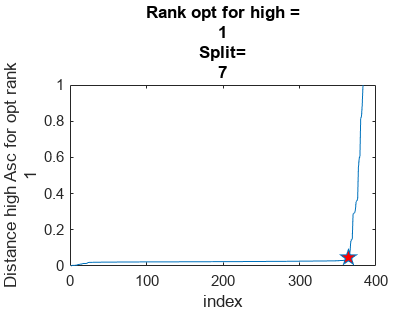

optrank_l = 1

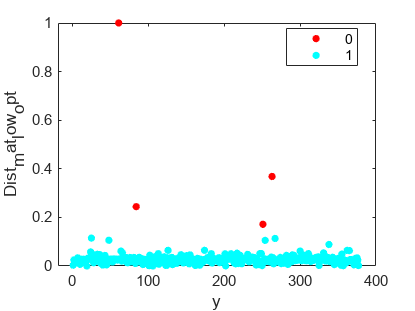

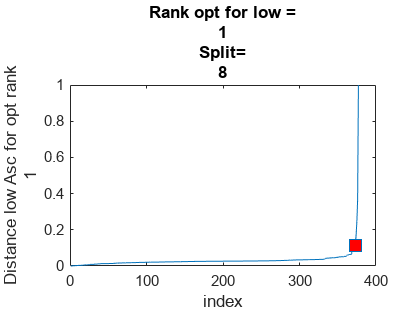

optrank_h = 1

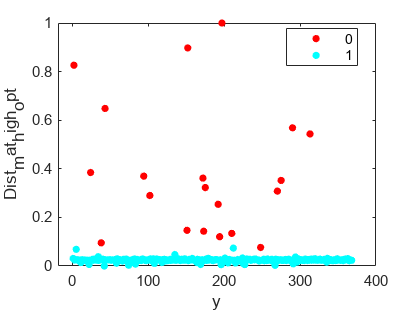

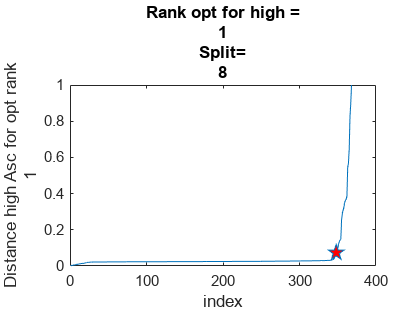

optrank_l = 1

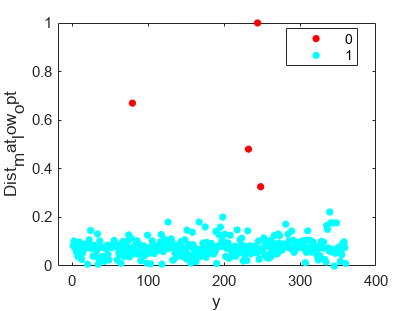

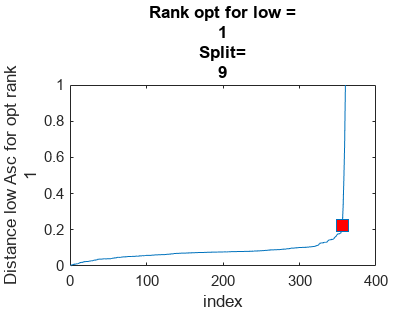

optrank_h = 1

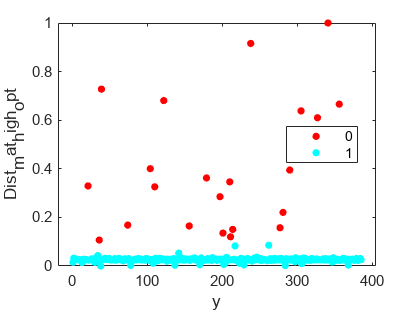

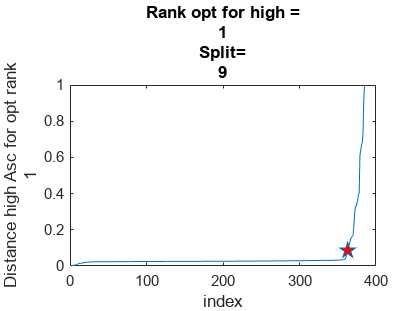

optrank_l = 1

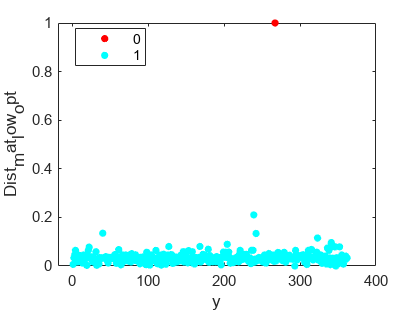

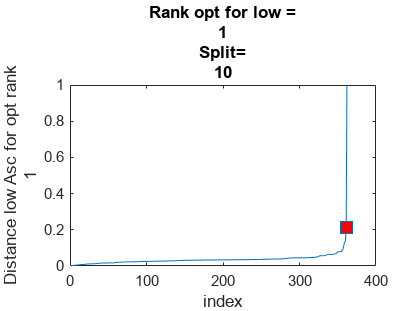

optrank_h = 1

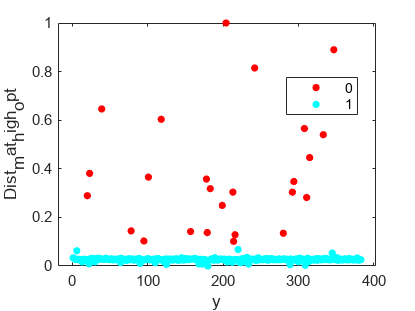

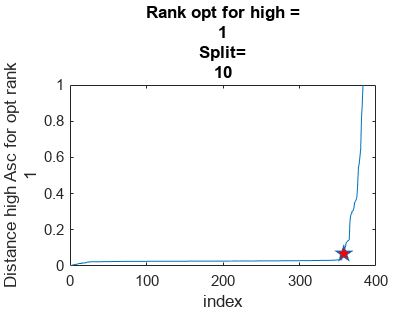

for j = [1,2,3,4,5,6,7,8,9,10]
    figure
    splitfolder=strcat('split',num2str(j));
    per =20;%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('weather_noisy_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);


        low=File(File(:,10)==1,1:9);
        T_low=low.';

        high=File(File(:,10)==2,1:9);
        T_high=high.';

        folder_l1=strcat('ACE_dist_8optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)


        ranks=[1,2,3,4,5,6,7,8];

        error_low = nan(size(ranks));
        numlow=length(T_low);
        Dist_mat_low_array_asc=nan(length(ranks),numlow);
        threshold_rank_l=nan(size(ranks));
        elbow_indx_rank_l=nan(size(ranks));

        for i = ranks
            
            cd C:\Users\shukl\Documents\GitHub\Daily_Weather\

            T_low_temp=T_low;
            Dist_mat_low=[];


            BF_low=l1pca_BF(T_low,i,1,10,10,'');
            for k = 1 : numlow
                A=T_low(:,k);
                Dist_mat_low(k)=norm((A-(BF_low*BF_low.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_low,[],"all");
            max_val=max(Dist_mat_low,[],"all");
            Dist_mat_low= Dist_mat_low-min_val;%]/[max_val-min_val]
            Dist_mat_low=Dist_mat_low /(max_val-min_val);


            Dist_mat_low_array_asc(i,:)=Dist_mat_low;
            [Dist_mat_low_asc,Indx_l]=sort(Dist_mat_low,"ascend");


            [elbow_l_err_angle,elbow_indx_l]=knee_pt_angle(Dist_mat_low_asc);

            error_low(i)=elbow_l_err_angle;
            threshold_rank_l(i)=Dist_mat_low_asc(elbow_indx_l);
            elbow_indx_rank_l(i)=elbow_indx_l;


%             figure
%             plot(Dist_mat_low_asc,'-p',"MarkerIndices",(elbow_indx_l),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance low Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])
        end

        [~,optrank_l]= max(error_low)

        Dist_mat_low_opt=Dist_mat_low_array_asc(optrank_l,:);
        threshold_dist_l= threshold_rank_l(optrank_l);
        elbow_indx_l_opt=elbow_indx_rank_l(optrank_l);

        ind_O_l=find(Dist_mat_low_opt>threshold_dist_l);
        ind_I_l=find(Dist_mat_low_opt<=threshold_dist_l);


        cluster_l=zeros(size(Dist_mat_low_opt));
        cluster_l(ind_I_l)=1;
        figure
        y= 1:1:length(low);
        numGroups = length(unique(cluster_l));
        gscatter(y,Dist_mat_low_opt,cluster_l,hsv(numGroups))

        figure
        plot(sort(Dist_mat_low_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_l_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance low Asc for opt rank",num2str(optrank_l)])
        title(['Rank opt for low =',num2str(optrank_l),"Split=",num2str(j)])
        ind_O_l;


        T_low_temp(:,ind_O_l)=[];
        length(T_low_temp);


        Final_low=T_low_temp';
        Final_low(:,10)=1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_high = nan(size(ranks));
        numhigh=length(T_high);
        Dist_mat_high_array_asc=nan(length(ranks),numhigh);
        threshold_rank_h=nan(size(ranks));
        elbow_indx_rank_h=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Daily_Weather\

            T_high_temp=T_high;
            Dist_mat_high=[];


            BF_high=l1pca_BF(T_high,i,1,10,10,'');
            for k = 1 : numhigh
                A=T_high(:,k);
                Dist_mat_high(k)=norm((A-(BF_high*BF_high.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_high,[],"all");
            max_val=max(Dist_mat_high,[],"all");
            Dist_mat_high= Dist_mat_high-min_val;%]/[max_val-min_val]
            Dist_mat_high=Dist_mat_high /(max_val-min_val);


            Dist_mat_high_array_asc(i,:)=Dist_mat_high;
            [Dist_mat_high_asc,Indx_h]=sort(Dist_mat_high,"ascend");


            [elbow_h_err,elbow_indx_h]=knee_pt_angle((Dist_mat_high_asc));

            error_high(i)=elbow_h_err;
            threshold_rank_h(i)=Dist_mat_high_asc(elbow_indx_h);
            elbow_indx_rank_h(i)=elbow_indx_h;

%             figure
%             plot(Dist_mat_high_asc,'-p',"MarkerIndices",(elbow_indx_h),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance high Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])

        end

        [~,optrank_h]= max(error_high)

        Dist_mat_high_opt=Dist_mat_high_array_asc(optrank_h,:);
        threshold_dist_h= threshold_rank_h(optrank_h);
        elbow_indx_h_opt=elbow_indx_rank_h(optrank_h);

        ind_O_h=find(Dist_mat_high_opt>threshold_dist_h);
        ind_I_h=find(Dist_mat_high_opt<=threshold_dist_h);


        cluster_h=zeros(size(Dist_mat_high_opt));
        cluster_h(ind_I_h)=1;
        figure
        y= 1:1:length(high);
        numGroups = length(unique(cluster_h));
        gscatter(y,Dist_mat_high_opt,cluster_h,hsv(numGroups))

        figure
        plot(sort(Dist_mat_high_opt,"ascend"),'-p',"MarkerIndices",(elbow_indx_h_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance high Asc for opt rank",num2str(optrank_h)])
        title(['Rank opt for high =',num2str(optrank_h),"Split=",num2str(j)])
        ind_O_h;

        T_high_temp(:,ind_O_h)=[];
        length(T_high_temp);

        Final_high=T_high_temp';
        Final_high(:,10)=2;

        cd C:\Users\shukl\Documents\GitHub\Daily_Weather\
        cd (splitfolder)
        cd (folder)

        cd (folder_l1)

        L1pca_file=(horzcat(Final_low.',Final_high.')).';

        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:10)=  ["air_pressure_9am", "air_temp_9am",	"avg_wind_direction_9am", "avg_wind_speed_9am", "max_wind_direction_9am", "max_wind_speed_9am", "rain_accumulation_9am", "rain_duration_9am","relative_humidity_9am", "relative_humidity_3pm"];
        filel1pca=strcat('weather_noisy_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca);
    end
end